## Setting

Frequencies and time vectors:

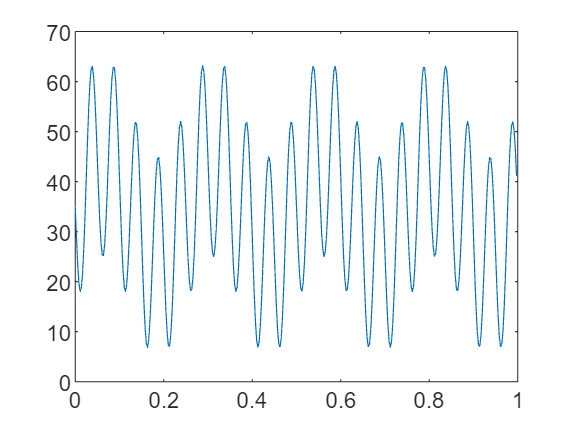

clear;
% sine waves
f = 361; % Sampling Frequency
n=f; % Sample Size
T = (0:n-1)/f; % Time Vector
F = (0:n-1)*f/n; % Frequency Vector
S=35+10*sin(2*pi*4*T)-20*sin(2*pi*20*T);
plot(T, S)

## Noisy Signal

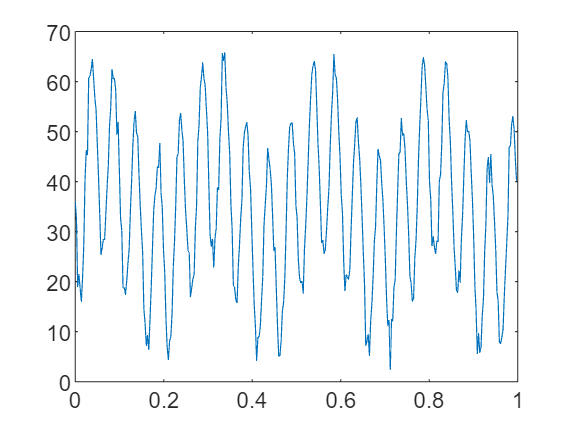

V = S+2*randn(size(T));
plot(T, V)

## FFT

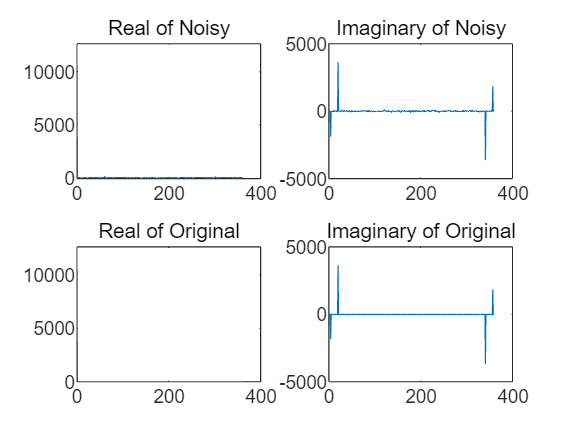

fftV = fft(V);
fftS = fft(S);
subplot(2, 2, 1)
plot(F, real(fftV))
subtitle("Real of Noisy")
subplot(2, 2, 2)
plot(F, imag(fftV))
subtitle("Imaginary of Noisy")
subplot(2, 2, 3)
plot(F, real(fftS))
subtitle("Real of Original")
subplot(2, 2, 4)
plot(F, imag(fftS))
subtitle("Imaginary of Original")

fftVs = fftshift(fftV);
fftSs = fftshift(fftS);
Fsh = F-(n/2+mod(n,2)/2)*f/n;


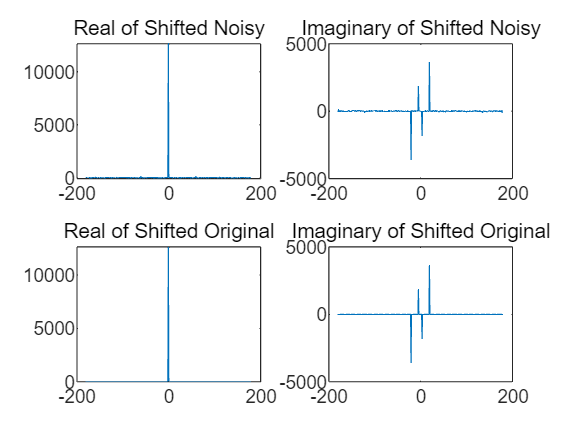

subplot(2, 2, 1)
plot(Fsh, real(fftVs))
subtitle("Real of Shifted Noisy")
subplot(2, 2, 2)
plot(Fsh, imag(fftVs))
subtitle("Imaginary of Shifted Noisy")
subplot(2, 2, 3)
plot(Fsh, real(fftSs))
subtitle("Real of Shifted Original")
subplot(2, 2, 4)
plot(Fsh, imag(fftSs))
subtitle("Imaginary of Shifted Original")

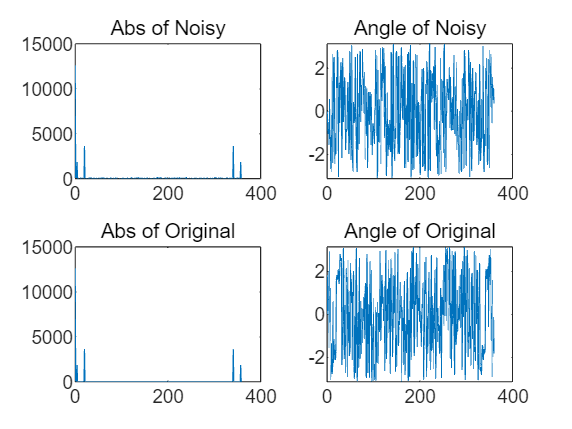


subplot(2, 2, 1)
plot(F, abs(fftV))
subtitle("Abs of Noisy")
subplot(2, 2, 2)
plot(F, angle(fftV))
subtitle("Angle of Noisy")
subplot(2, 2, 3)
plot(F, abs(fftS))
subtitle("Abs of Original")
subplot(2, 2, 4)
plot(F, angle(fftS))
subtitle("Angle of Original")

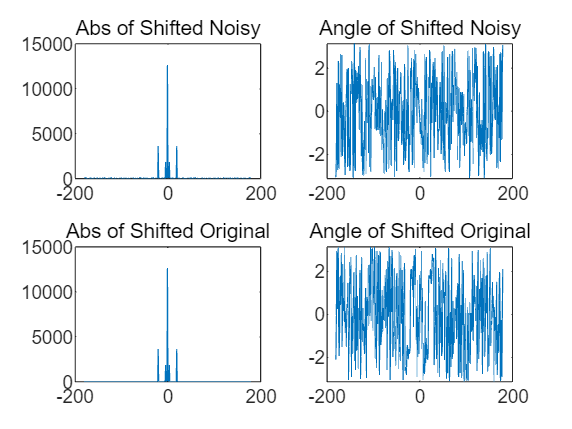


subplot(2, 2, 1)
plot(Fsh, abs(fftVs))
subtitle("Abs of Shifted Noisy")
subplot(2, 2, 2)
plot(Fsh, angle(fftVs))
subtitle("Angle of Shifted Noisy")
subplot(2, 2, 3)
plot(Fsh, abs(fftSs))
subtitle("Abs of Shifted Original")
subplot(2, 2, 4)
plot(Fsh, angle(fftSs))
subtitle("Angle of Shifted Original")

### Scaled FFT

posIdx = Fsh<0;
sfftV1 = fftV(posIdx)/n; sfftV1(2:end-1) = sfftV1(2:end-1)*2;
sfftS1 = fftS(posIdx)/n; sfftS1(2:end-1) = sfftS1(2:end-1)*2;
sF = 0:n/2-mod(n,2)*.5;

colororder([1 0 0; 0 1 0; 0 0 1]);
subplot(2,2,1)
subtitle('Original: Abs')
plot(sF, abs(sfftS1))
subplot(2,2,2)
plot(sF, angle(sfftS1))
subtitle('Angle')
subplot(2,2,3)
subtitle('Noisy: Abs')
plot(sF, abs(sfftV1))
subplot(2,2,4)
subtitle('Angle')
plot(sF, angle(sfftV1))

## Predicting Shifted Signals

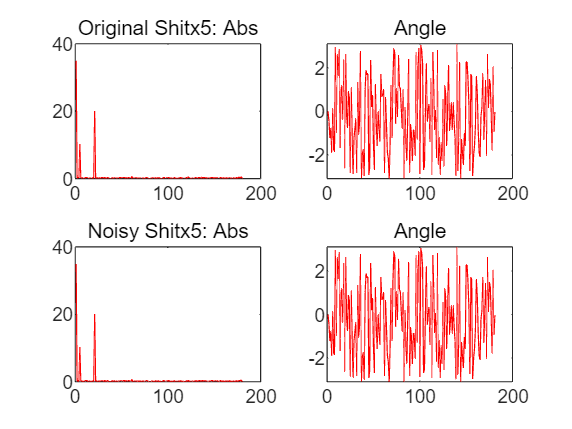

oV = circshift(V, 5);
fftoS1 = fft(oV)/n;
fftoS1 = fftoS1(posIdx);
fftoS1(2:end-1) = fftoS1(2:end-1)*2;


fftoV1 = fft(oV)/n;
fftoV1 = fftoV1(posIdx);
fftoV1(2:end-1) = fftoV1(2:end-1)*2;

subplot(2,2,1)
plot(abs(fftoS1))
subtitle("Original Shitx5: Abs")
subplot(2,2,2)
plot(angle(fftoS1))
subtitle("Angle")
subplot(2,2,3)
plot(abs(fftoV1))
subtitle("Noisy Shitx5: Abs")
subplot(2,2,4)
plot(angle(fftoV1))
subtitle("Angle")

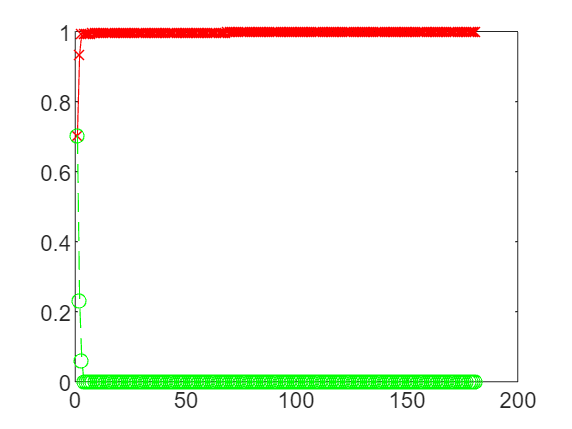


EspecVo = abs(fftoV1).^2;
[yo, yr]=sort(EspecVo, 'descend');
subplot(1,1,1)
plot(cumsum(yo)/sum(yo), '-x')
hold on
plot(yo/sum(yo), '--o')
hold off